close all;
clear;
load("C:\Users\lecci\Desktop\UNICT\Quarto Anno\Biomedical Systems\exercise\BCI_Project\s27.mat")
fs=eeg.srate;
ts=1/fs;
Ntrials=eeg.n_imagery_trials; %100 ma in realtà sono 100 per classe, quindi 200
trialsLeft=eeg.imagery_left(1:64,:)'; %CHANNELS FROM 1 TO 64 ARE FOR EEG
trialsRight=eeg.imagery_right(1:64,:)'; %FROM 64 TO 68 ARE FOR EMG (we don't need them)
Nevents=eeg.imagery_event; %sembrano tutti 0 ma ci sono 100 "1"
imagery_event_indices=find(Nevents==1);

filtered_left_imagery=filter(alphabeta_Filter,trialsLeft);
filtered_right_imagery=filter(alphabeta_Filter,trialsRight);

filtered_left_imagery_active=zeros((3*fs)*Ntrials,64);
filtered_right_imagery_active=zeros((3*fs)*Ntrials,64);
for i=1:Ntrials
    filtered_left_imagery_active(1+(i-1)*3*fs:i*3*fs,:)=filtered_left_imagery(imagery_event_indices(i):imagery_event_indices(i)+fs*3-1,:);
    filtered_right_imagery_active(1+(i-1)*3*fs:i*3*fs,:)=filtered_right_imagery(imagery_event_indices(i):imagery_event_indices(i)+fs*3-1,:);
end                
left_dataset=zeros(3*fs,64,Ntrials);
right_dataset=zeros(3*fs,64,Ntrials);
dataset=struct('data',cell(1,2*Ntrials),'label',cell(1,2*Ntrials));

for i=1:Ntrials
left_dataset(:,:,i)=filtered_left_imagery(imagery_event_indices(i):imagery_event_indices(i)+3*fs-1,:);
right_dataset(:,:,i)=filtered_right_imagery(imagery_event_indices(i):imagery_event_indices(i)+3*fs-1,:);
%right_dataset (also left_dataset) will be #samples x #channels x #epochs
%filtered_right_imagery_active will be #samples x #channels

dataset(2*i-1).data=left_dataset(:,:,i);
dataset(2*i-1).label='l';

dataset(2*i).data=right_dataset(:,:,i);
dataset(2*i).label='r';
end

dataset_random=dataset(randperm(length(dataset)));  %  FONDAMENTALE NEL TRAINING


n_train=round(2*Ntrials*percentage);
n_test=2*Ntrials-n_train;

%dataset_random(epoca ma arriva fino a 200).data(sample,canale)
%dataset_random(epoca ma arriva fino a 200).label è l per left, r per right


%leftdata=filtered_left_imagery_active(randperm(size(filtered_left_imagery_active,1)),:);
%rightdata=filtered_right_imagery_active(randperm(size(filtered_right_imagery_active,1)),:);
%questi non si possono randomizzare perché le epoche sono tutte incucchiate
leftdata=filtered_left_imagery_active;
rightdata=filtered_right_imagery_active;
%RANDOMIZING VECTORS

right_dataset=right_dataset(:,:,randperm(size(right_dataset,3)));
left_dataset=left_dataset(:,:,randperm(size(left_dataset,3)));
%randomizing epoch order 

percentage=0.90;
%DATASET DIVISION
rightdata_train=rightdata(1:round(percentage * length(rightdata)),:);
rightdata_test=rightdata(round(percentage * length(rightdata))+1:end,:);
leftdata_train=leftdata(1:round(percentage * length(leftdata)),:);
leftdata_test=leftdata(round(percentage * length(leftdata))+1:end,:);
%all epochs together
rightepoch_train=right_dataset(:,:,1:round(percentage * size(right_dataset,3)));
rightepoch_test=right_dataset(:,:,round(percentage * size(right_dataset,3))+1:end);
leftepoch_train=left_dataset(:,:,1:round(percentage * size(left_dataset,3)));
leftepoch_test=left_dataset(:,:,round(percentage * size(left_dataset,3))+1:end);
%dataset with single epochs splitted

SPATIAL FILTERING

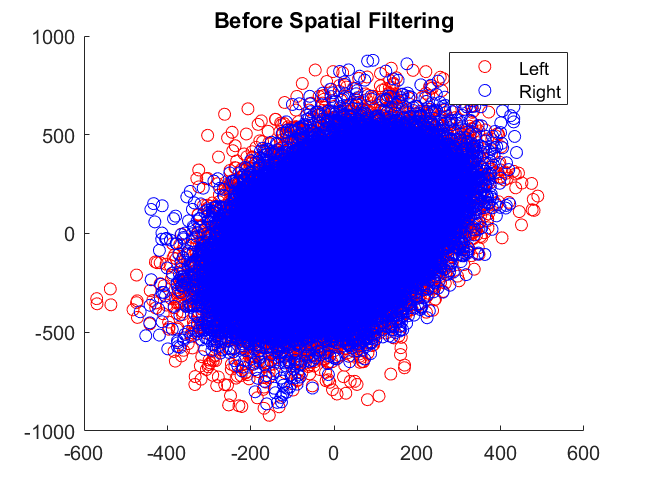

figure ; %class è 14x50k
% scatter ( right_dataset(:,1,:),right_dataset(:,2,:) , 'r');
% hold on ;
% scatter ( left_dataset(:,1,:),left_dataset(:,2,:), 'b');
scatter ( rightdata_train(:,13),rightdata_train(:,50) , 'r');
hold on ;
scatter ( leftdata_train(:,13),leftdata_train(:,50), 'b');
%QUI NELLO SCATTER STO METTENDO SOLO I CANALI 1 E 2 CHE STO DECIDENDO
%ESSERE IMPORTANTI, NELL'HOMEWORK HA SENSO PRENDERE SOLO QUELLI CHE
%DECIDIAMO ESSERE IMPORTANTI
%NORMALMENTE per motor imagery si scelgono i canali C3 e C4 del sistema 10-20
%in quanto sono quelli più vicini alla motor cortex che si attiva quando 
%si immagina un movimento
%invece nel sistema 10-10 si può scegliere tra C3 o C1 o C5, e C2 o C4 o C6
%NOI ABBIAMO USATO 10-10 MA QUALI SONO I CANALI C3 ECC?????????????????????
title ('Before Spatial Filtering');
legend ('Left ', 'Right ');


%CALCOLO E APPLICAZIONE DEL CSP

C1=cov(rightdata_train)

C1 = 	1.0e+05 *

    0.6379    0.4853    0.4053    0.2590    0.2816    0.2872    0.2896    0.1928    0.2092    0.1949    0.1824    0.1211    0.1191    0.1265    0.1339    0.0851    0.0756    0.0663    0.0643    0.0262    0.0243    0.0343    0.0490    0.0721    0.0110   -0.0069    0.0079    0.0611    0.0247    0.0009    0.0317    0.0686    0.6401    0.8003    0.7792    0.4253    0.3902    0.2426    0.2282    0.2028    0.3626    0.3827    0.2300    0.0766    0.0699    0.1455    0.1680    0.1111    0.1017    0.0914
    0.4853    0.5481    0.3576    0.2195    0.2243    0.2400    0.3015    0.1852    0.1660    0.1658    0.1599    0.1086    0.1067    0.1169    0.1368    0.0851    0.0728    0.0616    0.0584    0.0245    0.0240    0.0358    0.0504    0.0778    0.0158   -0.0042    0.0102    0.0614    0.0249    0.0008    0.0293    0.0634    0.4667    0.5371    0.5231    0.3369    0.3142    0.2083    0.2015    0.1934    0.2781    0.2879    0.1873    0.1044    0.0969    0.1375    0.1507    0.1020  

C2=cov(leftdata_train)

C2 = 	1.0e+05 *

    0.5835    0.4487    0.3715    0.2388    0.2609    0.2689    0.2742    0.1775    0.1922    0.1795    0.1700    0.1132    0.1101    0.1171    0.1271    0.0848    0.0686    0.0598    0.0589    0.0242    0.0227    0.0317    0.0476    0.0692    0.0146   -0.0047    0.0065    0.0580    0.0227    0.0026    0.0301    0.0647    0.5815    0.7396    0.7082    0.3806    0.3558    0.2235    0.2070    0.1734    0.3259    0.3384    0.2013    0.0695    0.0667    0.1348    0.1574    0.1050    0.0965    0.0839
    0.4487    0.5208    0.3340    0.2061    0.2103    0.2276    0.2908    0.1736    0.1538    0.1548    0.1516    0.1039    0.1012    0.1105    0.1333    0.0877    0.0695    0.0576    0.0554    0.0228    0.0235    0.0339    0.0511    0.0789    0.0179   -0.0034    0.0092    0.0613    0.0242    0.0019    0.0283    0.0613    0.4251    0.4852    0.4468    0.2971    0.2898    0.1965    0.1900    0.1759    0.2364    0.2424    0.1663    0.1145    0.1097    0.1353    0.1451    0.0995  

M=C2^-1*C1

M =     1.0029   -0.0221    0.0234    0.0213    0.0089   -0.0257   -0.0264   -0.0047    0.0078    0.0156    0.0248    0.0236    0.0084    0.0042    0.0193    0.0127    0.0047    0.0029    0.0112    0.0024   -0.0099   -0.0116   -0.0078   -0.0807   -0.0302   -0.0129   -0.0063   -0.0090   -0.0012   -0.0030    0.0179    0.0384   -0.0184   -0.1216   -0.2599   -0.0515    0.0142    0.0300    0.0478    0.0688   -0.0846   -0.0578   -0.0051    0.1408    0.1613    0.0716    0.0384    0.0402    0.0632    0.0837
   -0.0160    1.0143    0.0042   -0.0056    0.0046    0.0091    0.0113   -0.0076   -0.0104   -0.0035   -0.0048   -0.0073   -0.0055   -0.0040   -0.0173   -0.0304   -0.0157   -0.0069   -0.0065    0.0002   -0.0046   -0.0060   -0.0227   -0.0268   -0.0060    0.0014   -0.0062   -0.0168   -0.0079    0.0013   -0.0005   -0.0072   -0.0036    0.0449    0.1521    0.0400   -0.0018   -0.0121   -0.0219   -0.0359    0.0292    0.0719    0.0024   -0.0725   -0.0689   -0.0279   -0.0133   -0.0125   -0.0243   -0

[L,E]=eig(M)

L =    -0.0355   -0.0170    0.0136    0.0054    0.0710    0.0454    0.0671   -0.0800   -0.0611    0.0455    0.0425    0.0310   -0.0163   -0.0666   -0.0903   -0.0471    0.0399    0.0298   -0.0171    0.0138   -0.0465    0.0042   -0.0577    0.0347   -0.0095    0.0124    0.0035   -0.0228   -0.0799    0.1377    0.0000    0.0772   -0.0074    0.0445    0.1217    0.0331    0.0088   -0.0172   -0.0088    0.1379    0.0131   -0.0486   -0.0263    0.0675   -0.1577    0.0731    0.0038    0.0753   -0.0947   -0.0829
    0.0029    0.0452   -0.0112    0.0126   -0.0247    0.0353    0.0076    0.0007   -0.0245   -0.0763   -0.0101   -0.0433   -0.0183   -0.0214    0.0238   -0.0013   -0.0070   -0.0125    0.0203   -0.0365    0.0354    0.0318   -0.0347    0.0433   -0.0218    0.0113   -0.0422    0.0474   -0.0202   -0.0959    0.0238    0.0035    0.0340   -0.0670   -0.0641    0.0487   -0.0503   -0.0201    0.0162   -0.0905    0.0109    0.0023    0.0105   -0.0360    0.0136   -0.0290   -0.0164   -0.0321   -0.0082    0

E =     1.2960         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.2768         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

E=diag(E) %rendo autovalori una colonna per poterli ordinare

E =     1.2960
    1.2768
    1.2575
    1.2227
    1.2013
    1.1846
    0.8374
    0.8488
    1.1570
    1.1503


[E,indexes]=sort(E,'descend') %ordino autovalori in maniera decrescente e mi prendo l'ordine in cui li metto

E =     1.2960
    1.2768
    1.2575
    1.2227
    1.2013
    1.1846
    1.1570
    1.1503
    1.1337
    1.1294


indexes =      1
     2
     3
     4
     5
     6
     9
    10
    14
    15


L=L(:,indexes) %ordino autovettori nello stesso ordine degli autovalori

L =    -0.0355   -0.0170    0.0136    0.0054    0.0710    0.0454   -0.0611    0.0455   -0.0666   -0.0903   -0.0471    0.0298   -0.0171   -0.0465    0.0138    0.0042    0.0124    0.0035   -0.0228   -0.0799    0.1377    0.0000    0.1217   -0.0172   -0.0088    0.1379    0.0131   -0.0486   -0.0263    0.0675    0.0731    0.0038    0.0753   -0.0947   -0.0829   -0.0023    0.0075    0.0691   -0.0686    0.0932   -0.0875   -0.0142    0.0324    0.0215   -0.0533    0.0393   -0.0437   -0.0217   -0.1685   -0.1577
    0.0029    0.0452   -0.0112    0.0126   -0.0247    0.0353   -0.0245   -0.0763   -0.0214    0.0238   -0.0013   -0.0125    0.0203    0.0354   -0.0365    0.0318    0.0113   -0.0422    0.0474   -0.0202   -0.0959    0.0238   -0.0641   -0.0201    0.0162   -0.0905    0.0109    0.0023    0.0105   -0.0360   -0.0290   -0.0164   -0.0321   -0.0082    0.0115    0.0031    0.0473    0.0363    0.0261   -0.0270    0.0047   -0.0707    0.0000    0.0024    0.0597   -0.0061    0.0344   -0.0127    0.0065    0

SpatialFilter=[L(:,1) L(:,end)]

SpatialFilter =    -0.0355    0.0671
    0.0029    0.0076
   -0.0595    0.0030
    0.1112   -0.1100
   -0.0360    0.0130
    0.0137    0.0319
   -0.0077   -0.0167
    0.0002    0.0350
    0.0036    0.0008
    0.0195   -0.1133


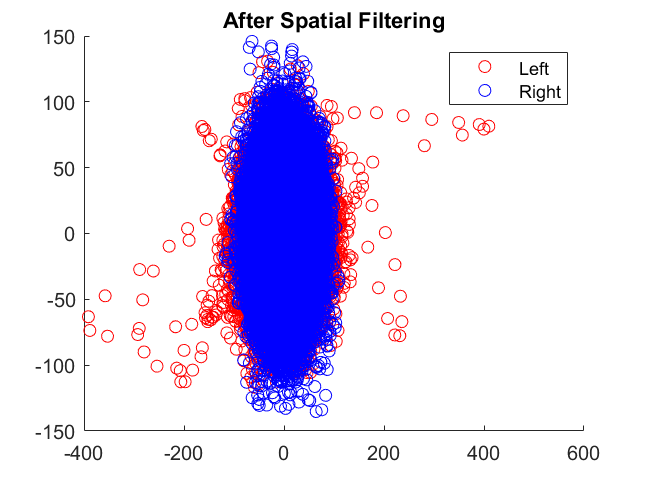

Newclass1_test=SpatialFilter'*rightdata_test'; %riduciamo dimensione dataset e "separiamo" le classi
Newclass2_test=SpatialFilter'*leftdata_test';
Newclass1_train=SpatialFilter'*rightdata_train';
Newclass2_train=SpatialFilter'*leftdata_train';
for i=1:1:size(rightepoch_test,3)
    Newclass1_epoch_test(:,:,i)=SpatialFilter'*rightepoch_test(:,:,i)';
    Newclass2_epoch_test(:,:,i)=SpatialFilter'*leftepoch_test(:,:,i)';
end


figure ;
scatter ( Newclass1_train(1,:) ,Newclass1_train(2,:), 'r');
hold on ;
scatter ( Newclass2_train(1,:),Newclass2_train(2,:), 'b');
%QUI PLOTTIAMO TUTTI E SOLO I CANALI CHE ABBIAMO, CHE ORA SONO SOLO 2, NEL
%NUOVO SISTEMA DI RIFERIMENTO perché tutto il dataset è convogliato in un
%due vettori che hanno il significato di varianza
title ('After Spatial Filtering');
legend ('Left ', 'Right ');

%SI VEDE CHE CI PROVANO AD ESSERE QUELLA ROSSA ORIZZONTALE E QUELLA BLU
%VERTICALE MA SONO TROPPO SIMILI TRA LORO

LDA

mu1=mean(Newclass1_train,2);
mu2=mean(Newclass2_train,2);
Sw=cov(Newclass1_train')+cov(Newclass2_train');
mu=mean([mu1,mu2],2);
Sb=50000*((mu1-mu)*(mu1-mu)'+(mu2-mu)*(mu2-mu)');
M=Sw^-1*Sb;
[L,E]=eig(M);
E=diag(E); 
[E,indexes]=sort(E,'descend'); 
L=L(:,indexes); 
w=L(:,1); 
b=-0.5*w'*(mu1+mu2);

disp('Train results')

Train results


TrainSignclass1=sign(mean(w'*Newclass1_train+b))

TrainSignclass1 = 1

TrainSignclass2=sign(mean(w'*Newclass2_train+b))

TrainSignclass2 = -1

% disp('test, all epochs together')
% mean(w'*Newclass1_test+b)
% mean(w'*Newclass2_test+b)
correct=0;
for i=1:1:size(Newclass1_epoch_test,3)
if((mean(w'*Newclass1_epoch_test(:,:,i)+b))*TrainSignclass1 >0)
    correct=correct+1;
end
end
correct=correct/size(Newclass1_epoch_test,3);
disp('Test results on the right class')

Test results on the right class


disp(correct);

    0.8000




correct=0;
for i=1:1:size(Newclass2_epoch_test,3)
if((mean(w'*Newclass2_epoch_test(:,:,i)+b))*TrainSignclass2 >0)
    correct=correct+1;
end
end
correct=correct/size(Newclass2_epoch_test,3);
disp('Test results on the left class')

Test results on the left class


disp(correct);

    0.9000



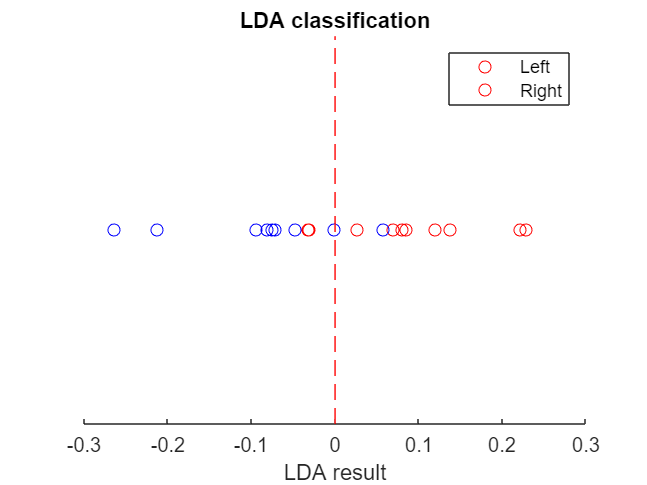


for i=1:1:size(Newclass2_epoch_test,3)
    class2mean(i)=(mean(w'*Newclass2_epoch_test(:,:,i)+b));
end
for i=1:1:size(Newclass1_epoch_test,3)
    class1mean(i)=(mean(w'*Newclass1_epoch_test(:,:,i)+b));
end
figure ;
scatter ( class1mean,0, 'r');
hold on ;
scatter ( class2mean,0, 'b');
hold on;
x = [0 0];  % Coordinate x per la linea verticale
y = ylim;   % Limiti dell'asse y
plot(x, y, 'r--');  % Plotta la linea rossa tratteggiata
title ('LDA classification');
xlabel('LDA result')
legend ('Left ', 'Right ');
set(gca, 'YColor', 'none');

provo a fare ciclo

TestAccuracy=0;
for j=1:1:9
load("C:\Users\lecci\Desktop\UNICT\Quarto Anno\Biomedical Systems\exercise\BCI_Project\s27.mat")
fs=eeg.srate;
ts=1/fs;
Ntrials=eeg.n_imagery_trials; %100 ma in realtà sono 100 per classe, quindi 200
trialsLeft=eeg.imagery_left(1:64,:)'; %CHANNELS FROM 1 TO 64 ARE FOR EEG
trialsRight=eeg.imagery_right(1:64,:)'; %FROM 64 TO 68 ARE FOR EMG (we don't need them)
Nevents=eeg.imagery_event; %sembrano tutti 0 ma ci sono 100 "1"
imagery_event_indices=find(Nevents==1);

filtered_left_imagery=filter(alphabeta_Filter,trialsLeft);
filtered_right_imagery=filter(alphabeta_Filter,trialsRight);

filtered_left_imagery_active=zeros((3*fs)*Ntrials,64);
filtered_right_imagery_active=zeros((3*fs)*Ntrials,64);
for i=1:Ntrials
    filtered_left_imagery_active(1+(i-1)*3*fs:i*3*fs,:)=filtered_left_imagery(imagery_event_indices(i):imagery_event_indices(i)+fs*3-1,:);
    filtered_right_imagery_active(1+(i-1)*3*fs:i*3*fs,:)=filtered_right_imagery(imagery_event_indices(i):imagery_event_indices(i)+fs*3-1,:);
end                
left_dataset=zeros(3*fs,64,Ntrials);
right_dataset=zeros(3*fs,64,Ntrials);
dataset=struct('data',cell(1,2*Ntrials),'label',cell(1,2*Ntrials));

for i=1:Ntrials
left_dataset(:,:,i)=filtered_left_imagery(imagery_event_indices(i):imagery_event_indices(i)+3*fs-1,:);
right_dataset(:,:,i)=filtered_right_imagery(imagery_event_indices(i):imagery_event_indices(i)+3*fs-1,:);
%right_dataset (also left_dataset) will be #samples x #channels x #epochs
%filtered_right_imagery_active will be #samples x #channels

dataset(2*i-1).data=left_dataset(:,:,i);
dataset(2*i-1).label='l';

dataset(2*i).data=right_dataset(:,:,i);
dataset(2*i).label='r';
end

dataset_random=dataset(randperm(length(dataset)));  %  FONDAMENTALE NEL TRAINING

percentage=j/10;
% n_train=round(2*Ntrials*percentage);
% n_test=2*Ntrials-n_train;

%dataset_random(epoca ma arriva fino a 200).data(sample,canale)
%dataset_random(epoca ma arriva fino a 200).label è l per left, r per right

%RANDOMIZING VECTORS

%leftdata=filtered_left_imagery_active(randperm(size(filtered_left_imagery_active,1)),:);
%rightdata=filtered_right_imagery_active(randperm(size(filtered_right_imagery_active,1)),:);
%questi non si possono randomizzare perché le epoche sono tutte incucchiate

%right_dataset=right_dataset(:,:,randperm(size(right_dataset,3)));
%left_dataset=left_dataset(:,:,randperm(size(left_dataset,3)));
%qui sopra invece randomizzo l'ordine delle epoche

leftdata=filtered_left_imagery_active;
rightdata=filtered_right_imagery_active;

%DATASET DIVISION
rightdata_train=rightdata(1:round(percentage * length(rightdata)),:);
rightdata_test=rightdata(round(percentage * length(rightdata))+1:end,:);
leftdata_train=leftdata(1:round(percentage * length(leftdata)),:);
leftdata_test=leftdata(round(percentage * length(leftdata))+1:end,:);

rightepoch_train=right_dataset(:,:,1:round(percentage * size(right_dataset,3)));
rightepoch_test=right_dataset(:,:,round(percentage * size(right_dataset,3))+1:end);
leftepoch_train=left_dataset(:,:,1:round(percentage * size(left_dataset,3)));
leftepoch_test=left_dataset(:,:,round(percentage * size(left_dataset,3))+1:end);

SPATIAL FILTERING

% figure ; %class è 14x50k
% % scatter ( right_dataset(:,1,:),right_dataset(:,2,:) , 'r');
% % hold on ;
% % scatter ( left_dataset(:,1,:),left_dataset(:,2,:), 'b');
% scatter ( rightdata_train(:,1),rightdata_train(:,2) , 'r');
% hold on ;
% scatter ( leftdata_train(:,1),leftdata_train(:,2), 'b');
%QUI NELLO SCATTER STO METTENDO SOLO I CANALI 1 E 2 CHE STO DECIDENDO
%ESSERE IMPORTANTI, NELL'HOMEWORK HA SENSO PRENDERE SOLO QUELLI CHE
%DECIDIAMO ESSERE IMPORTANTI
%NORMALMENTE per motor imagery si scelgono i canali C3 e C4 del sistema 10-20
%in quanto sono quelli più vicini alla motor cortex che si attiva quando 
%si immagina un movimento
%invece nel sistema 10-10 si può scegliere tra C3 o C1 o C5, e C2 o C4 o C6
%NOI ABBIAMO USATO 10-10 MA QUALI SONO I CANALI C3 ECC?????????????????????
% title ('Before Spatial Filtering');
% legend ('Left ', 'Right ');

%CALCOLO E APPLICAZIONE DEL CSP

C1=cov(rightdata_train);
C2=cov(leftdata_train);
M=C2^-1*C1;
[L,E]=eig(M);
E=diag(E) %rendo autovalori una colonna per poterli ordinare
[E,indexes]=sort(E,'descend'); %ordino autovalori in maniera decrescente e mi prendo l'ordine in cui li metto
L=L(:,indexes) %ordino autovettori nello stesso ordine degli autovalori
SpatialFilter=[L(:,1) L(:,end)];
Newclass1_test=SpatialFilter'*rightdata_test'; %riduciamo dimensione dataset e "separiamo" le classi
Newclass2_test=SpatialFilter'*leftdata_test';
Newclass1_train=SpatialFilter'*rightdata_train';
Newclass2_train=SpatialFilter'*leftdata_train';
for i=1:1:size(rightepoch_test,3)
    Newclass1_epoch_test(:,:,i)=SpatialFilter'*rightepoch_test(:,:,i)';
    Newclass2_epoch_test(:,:,i)=SpatialFilter'*leftepoch_test(:,:,i)';
end


% figure ;
% scatter ( Newclass1_train(1,:) ,Newclass1_train(2,:), 'r');
% hold on ;
% scatter ( Newclass2_train(1,:),Newclass2_train(2,:), 'b');
%QUI PLOTTIAMO TUTTI E SOLO I CANALI CHE ABBIAMO, CHE ORA SONO SOLO 2, NEL
%NUOVO SISTEMA DI RIFERIMENTO perché tutto il dataset è convogliato in un
%due vettori che hanno il significato di varianza
% title ('After Spatial Filtering');
% legend ('Left ', 'Right ');
%SI VEDE CHE CI PROVANO AD ESSERE QUELLA ROSSA ORIZZONTALE E QUELLA BLU
%VERTICALE MA SONO TROPPO SIMILI TRA LORO

LDA

mu1=mean(Newclass1_train,2);
mu2=mean(Newclass2_train,2);
Sw=cov(Newclass1_train')+cov(Newclass2_train');
mu=mean([mu1,mu2],2);
Sb=50000*((mu1-mu)*(mu1-mu)'+(mu2-mu)*(mu2-mu)');
M=Sw^-1*Sb;
[L,E]=eig(M);
E=diag(E); %rendo autovalori una colonna per poterli ordinare
[E,indexes]=sort(E,'descend'); %ordino autovalori in maniera decrescente e mi prendo l'ordine in cui li metto
L=L(:,indexes); %ordino autovettori nello stesso ordine degli autovalori
w=L(:,1); %solo autovettore associato ad autovalore più grande
b=-0.5*w'*(mu1+mu2);
%io voglio massimizzare la varianza TRA le due classi, per allontanarle tra loro
%e voglio minimizzare la varianza DENTRO le due classi, quindi "restringere lo spazio che occupano"

%per usare classificatore si fa mean(w'*osservazioni+b)
%disp('train')
segnoTrain1=sign(mean(w'*Newclass1_train+b));
segnoTrain2=sign(mean(w'*Newclass2_train+b));
% disp('test, all epochs together')
% mean(w'*Newclass1_test+b)
% mean(w'*Newclass2_test+b)
correct1=0;
for i=1:1:size(Newclass1_epoch_test,3)
if((mean(w'*Newclass1_epoch_test(:,:,i)+b))*segnoTrain1 >0)
    correct1=correct1+1;
end
end
correct1=correct1/size(Newclass1_epoch_test,3);
% disp('Test results on the right class')
% disp(correct);

correct2=0;
for i=1:1:size(Newclass2_epoch_test,3)
if((mean(w'*Newclass2_epoch_test(:,:,i)+b))*segnoTrain2 >0)
    correct2=correct2+1;
end
end
correct2=correct2/size(Newclass2_epoch_test,3);
% disp('Test results on the left class')
% disp(correct);
Testaccuracy(j)=correct1+correct2/2;
end

E =     2.4035
    1.9029
    1.8635
    1.7539
    1.6986
    1.6213
    1.5720
    1.5371
    1.5262
    1.4892


L =     0.0139    0.0927    0.0582    0.0119    0.0102    0.0840   -0.0700    0.0069    0.0635    0.2069    0.0498    0.0049    0.1200    0.0318    0.1063    0.0010   -0.0278   -0.0227   -0.0530   -0.0655    0.0945    0.0918    0.0333   -0.1124   -0.0456   -0.0211    0.0420   -0.0178   -0.0340    0.0199   -0.0367   -0.0343   -0.1167   -0.0286   -0.0618    0.0588   -0.0610   -0.1454    0.0724   -0.1020    0.0387    0.0514    0.1186   -0.0690    0.0314    0.0662   -0.0378    0.0296   -0.0194   -0.0946
   -0.0085   -0.1137   -0.1008   -0.0314    0.0471   -0.0045   -0.0288   -0.0380   -0.0336   -0.0405    0.0423   -0.0543   -0.0236   -0.0774   -0.0512    0.0454   -0.0063   -0.0761    0.1153    0.0425    0.0644   -0.0329    0.0852    0.0400    0.0452   -0.0301    0.0102   -0.0048   -0.0692   -0.0113    0.0412    0.0083    0.0396    0.0114    0.0312   -0.0254   -0.0391    0.0167   -0.0208    0.0756   -0.0280   -0.0054   -0.0216    0.0348   -0.0210    0.0019    0.0170    0.0251    0.0324    0

E =     1.7436
    1.6602
    1.5125
    1.4711
    1.4396
    1.4096
    1.3972
    1.3646
    1.3538
    1.3379


L =     0.0171    0.0246   -0.0368   -0.0002    0.1685    0.0007    0.0533    0.0064    0.0507    0.0053    0.0493    0.0008   -0.1307   -0.0615   -0.0118    0.1341   -0.0445    0.0241    0.0516    0.0745    0.0307   -0.0649    0.0042   -0.0032   -0.0948   -0.0660   -0.0731   -0.0238    0.0072   -0.0793   -0.0011    0.0635    0.0458   -0.0396    0.0332    0.1133    0.1017    0.0544   -0.0592    0.0571    0.1015   -0.0314    0.1233   -0.0312    0.0286    0.0782    0.0157   -0.1455   -0.0612   -0.0399
   -0.0096    0.0292    0.0341   -0.0228   -0.0191   -0.0463    0.0407    0.0308   -0.0442    0.0263    0.0060   -0.0557    0.1189   -0.0145   -0.0015   -0.0048    0.0451   -0.0692   -0.0306    0.0229   -0.0338    0.0767   -0.0814    0.0240   -0.0573    0.0546    0.0056    0.0073    0.0190    0.0168    0.0166   -0.0298   -0.0610   -0.0239   -0.0497    0.0252   -0.0362   -0.0153    0.0418   -0.0231   -0.0316   -0.0069   -0.0352    0.0552    0.0351    0.0425    0.0661    0.0071    0.0004    0

E =     1.5128
    1.4109
    1.3773
    1.3365
    1.3312
    1.2990
    1.2846
    1.2621
    1.2572
    1.2441


L =    -0.0176    0.1558   -0.0312    0.0726    0.0209   -0.0479   -0.0211    0.0484    0.0640    0.0738   -0.0938    0.1123    0.0853    0.0657    0.0418   -0.0031    0.0286   -0.0161   -0.0628    0.0228    0.0890    0.0337    0.0504   -0.0395    0.0548   -0.0869   -0.0226   -0.0070   -0.0878   -0.0521   -0.0142    0.0528   -0.0488   -0.0942   -0.1086    0.0982   -0.0376    0.0458   -0.0315   -0.0216    0.0111    0.0275   -0.0832    0.0806   -0.0688    0.0690   -0.0661   -0.1991    0.0695    0.0554
    0.0037   -0.0579   -0.0070    0.0116   -0.0155    0.0358   -0.0119    0.0207   -0.0120   -0.0207   -0.0044   -0.0253   -0.0082   -0.0970   -0.0270   -0.0582   -0.0425   -0.0025    0.0168    0.0047   -0.0420    0.0100    0.0329    0.0225   -0.0864    0.0251   -0.0675   -0.0102    0.0588    0.0291    0.0030   -0.1075    0.0155    0.0369    0.0066   -0.0025   -0.0310    0.0418    0.0102   -0.0264    0.0286   -0.0673    0.0375   -0.0071    0.0034   -0.0956    0.0405   -0.0119   -0.0025   -0

E =     1.4087
    1.3524
    1.3296
    1.2997
    1.2929
    1.2666
    1.2484
    0.7609
    0.7795
    1.2240


L =     0.0124   -0.0736    0.0340   -0.0199    0.0823   -0.0421    0.0001   -0.0710    0.0201   -0.0084    0.1356   -0.0319   -0.0474   -0.0617   -0.0545    0.0276   -0.0054    0.0448   -0.0200   -0.0920   -0.0312   -0.0257    0.0189    0.0211    0.0099    0.0387   -0.1433   -0.0282   -0.0250    0.0696    0.1510    0.1038   -0.0005    0.0572   -0.0047    0.0365   -0.0455    0.0659   -0.0726   -0.1271   -0.0517   -0.0953   -0.0227   -0.0159    0.0141   -0.0269    0.1059   -0.0265    0.0415    0.0641
   -0.0008    0.0364   -0.0025   -0.0244   -0.0125   -0.0378    0.0168    0.0097   -0.0281    0.0527    0.0116   -0.0382    0.0336    0.0276    0.0782   -0.0047    0.0219   -0.0804   -0.0353    0.0019    0.0674    0.0421   -0.0395   -0.0383    0.0377    0.0120    0.0280   -0.0163   -0.0792   -0.0245   -0.0380   -0.0778   -0.0227    0.0229   -0.0049    0.0174   -0.0115   -0.0196   -0.0190    0.0370    0.0672    0.0431    0.0193    0.0471   -0.0151    0.0114   -0.0032    0.0446   -0.0224   -0

E =     1.3867
    1.3381
    1.3073
    1.2727
    1.2807
    1.2201
    1.2074
    1.2025
    0.8029
    0.8083


L =    -0.0343   -0.0116   -0.0160    0.0401   -0.0232   -0.0518   -0.0209   -0.0124    0.0508    0.0175    0.0280   -0.0631   -0.0089   -0.0027    0.1350    0.1035    0.0703   -0.0537    0.0673    0.0691    0.0429   -0.0034   -0.0029   -0.0537    0.0037    0.1111   -0.0013   -0.0745    0.0461    0.1081    0.0075    0.0756   -0.0936    0.1286   -0.0594   -0.0681    0.0786   -0.0188   -0.0067   -0.0439   -0.1092   -0.0299    0.0513   -0.0406   -0.0157    0.0602    0.0437    0.0854    0.0295   -0.0827
    0.0053    0.0261    0.0175   -0.0098    0.0004   -0.0395    0.0024   -0.0501    0.0515   -0.0078   -0.0039    0.0004   -0.0080    0.0226   -0.1058   -0.0303   -0.0191    0.0016    0.0342   -0.0019   -0.0534   -0.0860   -0.0027    0.0785   -0.0188   -0.0476   -0.0143    0.0164    0.0041   -0.0436   -0.0614    0.0091    0.0114   -0.0742    0.0257   -0.0337   -0.0120   -0.0053   -0.0092    0.0392    0.0595   -0.0172   -0.0802   -0.0022   -0.0461   -0.0132    0.0238    0.0002    0.0238   -0

E =     1.3459
    1.3232
    1.2935
    1.2855
    1.2436
    1.2219
    0.8073
    0.8213
    1.1937
    1.1876


L =     0.0445   -0.0248   -0.0011    0.0216   -0.0641    0.0664   -0.0222   -0.0506    0.0312   -0.0888    0.0483    0.0322    0.0308   -0.0027   -0.0183   -0.0360    0.0118   -0.1181    0.0665    0.0559   -0.0035   -0.1559    0.0211    0.0393    0.0022    0.0592   -0.0084   -0.1108    0.0697   -0.0075   -0.0108    0.0408    0.0750    0.0424   -0.0265    0.0390   -0.0244    0.0658    0.1236   -0.1416    0.0144    0.0953    0.0258   -0.0039    0.0222    0.0081   -0.0563   -0.0165    0.0764    0.0474
   -0.0165    0.0267    0.0017   -0.0040    0.0005    0.0379    0.0315   -0.0411   -0.0014   -0.0050   -0.0273    0.0210   -0.0136   -0.0079    0.0019   -0.0450   -0.0379    0.0360   -0.0421   -0.0111    0.0142    0.0867    0.0293   -0.0452    0.0222   -0.0341   -0.0048   -0.0251   -0.0629    0.0049    0.0444    0.0359    0.0117   -0.0061    0.0013    0.0034    0.0212   -0.0590   -0.0025    0.0090   -0.0264    0.0058   -0.0573    0.0695   -0.0198    0.0295    0.0144    0.0074   -0.0628    0

E =     1.3382
    1.3050
    1.2980
    1.2507
    1.2468
    1.1993
    1.1829
    1.1778
    0.8246
    0.8314


L =    -0.0270    0.0464   -0.0119   -0.0083    0.0449    0.0298    0.0527    0.0456    0.0998   -0.0267   -0.0412    0.0431   -0.0042    0.0064   -0.0325    0.0990    0.0789   -0.0765   -0.0729    0.0280   -0.0078   -0.0117    0.0574   -0.1236    0.0084   -0.0877   -0.0590    0.0060   -0.0100   -0.0601    0.0533    0.0542   -0.0838    0.0240   -0.0822    0.0824   -0.0068   -0.0712    0.0361    0.1172   -0.0791    0.1086    0.0811   -0.0076    0.0470    0.0234    0.0242    0.0470   -0.0980    0.0654
    0.0057   -0.0374    0.0011   -0.0010   -0.0182    0.0555   -0.0054    0.0455    0.0053   -0.0176    0.0135   -0.0113    0.0165    0.0036    0.0035   -0.0063   -0.0658    0.0361   -0.0067    0.0177    0.0651    0.0166   -0.0373    0.0688    0.0316    0.0491    0.0108    0.0561   -0.0243   -0.0214   -0.0314    0.0261   -0.0277    0.0001    0.0565   -0.0231   -0.0049   -0.0258   -0.0006    0.0340   -0.0471   -0.0514   -0.0436    0.0451   -0.0781    0.0124   -0.0182   -0.0470    0.0181   -0

E =     1.3150
    1.2928
    1.2772
    1.2551
    1.2323
    1.1821
    1.1746
    0.8273
    1.1664
    0.8388


L =     0.0382   -0.0259   -0.0124    0.0096    0.0367   -0.0410    0.0014    0.0701    0.1075    0.0104   -0.0738    0.0179   -0.0101    0.0184   -0.0168   -0.0398   -0.0883    0.0060   -0.0736    0.0361   -0.0195   -0.0344   -0.0041    0.1181    0.0245   -0.0248   -0.0382   -0.0102   -0.0162   -0.1556   -0.0450    0.1759   -0.0231   -0.0320    0.0992   -0.0442   -0.0218    0.1146   -0.0070    0.0471   -0.0088    0.0258    0.0135    0.0117    0.0622    0.0168   -0.0294   -0.0106   -0.1018   -0.1414
   -0.0044    0.0386    0.0010   -0.0171   -0.0184   -0.0242   -0.0708    0.0018    0.0293   -0.0228    0.0208   -0.0129    0.0179   -0.0352   -0.0034   -0.0067    0.0209    0.0194   -0.0081   -0.0746   -0.0293    0.0292   -0.0001   -0.0615   -0.0118    0.0508    0.0200   -0.0017    0.0329    0.1511   -0.0064   -0.0315   -0.0189    0.0127    0.0296    0.0186   -0.0028   -0.0013   -0.0059   -0.0221   -0.0167    0.0231    0.0472   -0.0443    0.0160   -0.0443   -0.0558    0.0299    0.0680    0

E =     1.2960
    1.2768
    1.2575
    1.2227
    1.2013
    1.1846
    0.8374
    0.8488
    1.1570
    1.1503


L =    -0.0355   -0.0170    0.0136    0.0054    0.0710    0.0454   -0.0611    0.0455   -0.0666   -0.0903   -0.0471    0.0298   -0.0171   -0.0465    0.0138    0.0042    0.0124    0.0035   -0.0228   -0.0799    0.1377    0.0000    0.1217   -0.0172   -0.0088    0.1379    0.0131   -0.0486   -0.0263    0.0675    0.0731    0.0038    0.0753   -0.0947   -0.0829   -0.0023    0.0075    0.0691   -0.0686    0.0932   -0.0875   -0.0142    0.0324    0.0215   -0.0533    0.0393   -0.0437   -0.0217   -0.1685   -0.1577
    0.0029    0.0452   -0.0112    0.0126   -0.0247    0.0353   -0.0245   -0.0763   -0.0214    0.0238   -0.0013   -0.0125    0.0203    0.0354   -0.0365    0.0318    0.0113   -0.0422    0.0474   -0.0202   -0.0959    0.0238   -0.0641   -0.0201    0.0162   -0.0905    0.0109    0.0023    0.0105   -0.0360   -0.0290   -0.0164   -0.0321   -0.0082    0.0115    0.0031    0.0473    0.0363    0.0261   -0.0270    0.0047   -0.0707    0.0000    0.0024    0.0597   -0.0061    0.0344   -0.0127    0.0065    0

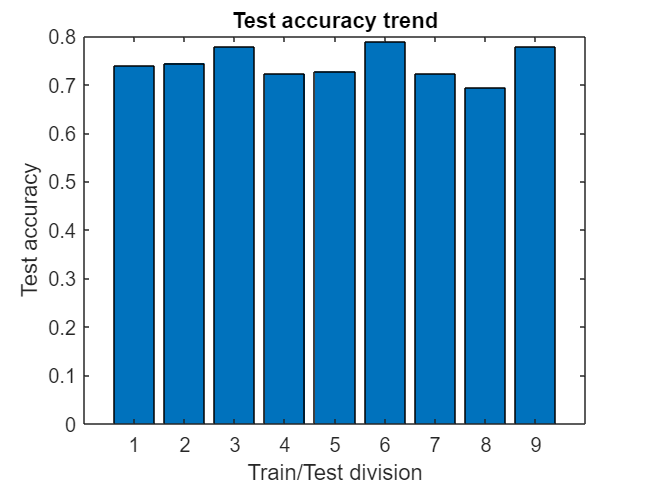

figure
bar(Testaccuracy);
xlim([0 10]);
xlabel('Train/Test division')
ylabel('Test accuracy')
title('Test accuracy trend')